# **2108332 Adjustment Computation**

## **LAB 3** Adjustment with observation equations

**ชื่อ-นามสกุล: วสุพล คล้ายขำ**

**รหัสประจำตัวนิสิต: 6631137221**

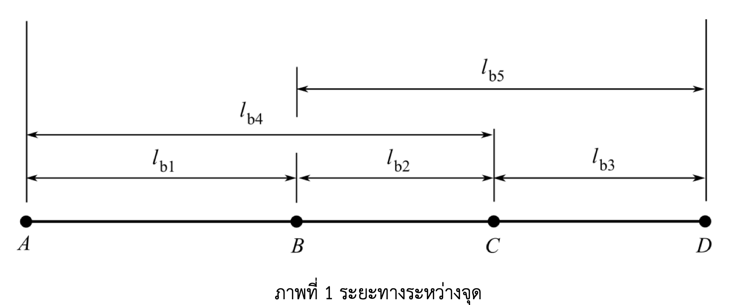

- ระยะทางระหว่างจุด A , B , C และ D ถูกรังวัดมาดังแสดงในภาพที่ 1 ผลลัพธ์แสดงอยู่ในตารางต่อไปนี้

ให้เขียนสคริปต์ของ MATLAB ปรับแก้วิธีกำลังสองน้อยที่สุดแบบใช้เฉพาะค่ารังวัดเพื่อหาระยะ AB , BC , CD ที่ปรับแก้แล้ว

clear
format long g
syms la1 la2 la3
lb1 = 20.011;
lb2 = 9.985;
lb3 = 10.003;
lb4 = 29.982;
lb5 = 20.005;
v1 = la1 - lb1;
v2 = la2 - lb2;
v3 = la3 - lb3;
v4 = la1 + la2 - lb4;
v5 = la2 + la3 - lb5;
phi = v1^2 + v2^2 + v3^2 + v4^2 + v5^2;
diff_v1 = diff(phi,la1);
diff_v2 = diff(phi,la2);
diff_v3 = diff(phi,la3);
eqnj1 = diff_v1 == 0;
eqnj2 = diff_v2 == 0;
eqnj3 = diff_v3 == 0;
[a,b] = equationsToMatrix([eqnj1,eqnj2,eqnj3],[la1,la2,la3]);
x = double(a \ b);
fprintf("AB = %.3f m",x(1))

AB = 20.004 m

fprintf("BC = %.3f m",x(2))

BC = 9.986 m

fprintf("CD = %.3f m",x(3))

CD = 10.011 m

2. ภาพที่ 2 แสดงโครงข่ายงานระดับ จุด A เป็นจุดที่ทราบค่าระดับแล้ว มีค่าระดับ 281.310 ม.

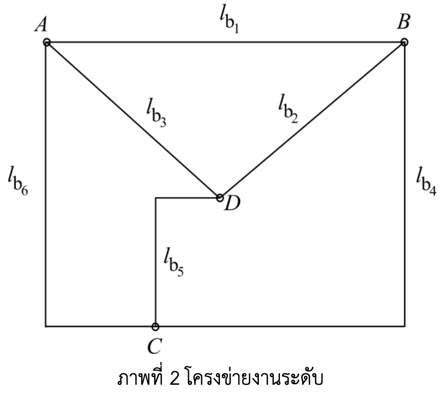

ค่ารังวัดที่ได้มีดังนี้

ให้เขียนสคริปต์ของ MATLAB ปรับแก้วิธีก าลังสองน้อยที่สุดแบบใช้เฉพาะค่ารังวัดเพื่อหาค่าระดับของจุด B , C , และ D

clear
format long g
syms v2 v3 v5
l = [11.976;10.948;22.934;21.044;31.893;8.981];
% 0 = -(lb1 + v1) + -(lb2 + v2) + (lb3 + v3) <=> v1 = -lb1-lb2+lb3-v2+v3
% 0 = (lb2 + v2) + (lb4 + v4) + -(lb5 + v5) <=> v4 = -lb2-lb4+lb5-v2+v5
% 0 = (lb5 + v5) + -(lb6 + v6) + -(lb3 + v3) <=> v6 = lb5-lb6-lb3+v5-v3
v1 =  - l(1) - l(2) + l(3) - v2 + v3;
v4 = - l(2) - l(4) + l(5) - v2 + v5;
v6 = l(5) - l(6) - l(3) + v5 - v3;
phi = v1^2 + v2^2 + v3^2 + v4^2 + v5^2 + v6^2;
equation_v2 = diff(phi,v2) == 0;
equation_v3 = diff(phi,v3) == 0;
equation_v5 = diff(phi,v5) == 0;
[a,b] = equationsToMatrix([equation_v2 equation_v3 equation_v5],[v2 v3 v5]);
x_ans = a \ b;
v1 = subs(v1,[v2 v3],[x_ans(1) x_ans(2)]);
v4 = subs(v4,[v2 v5],[x_ans(1) x_ans(3)]);
v6 = subs(v6,[v3 v5],[x_ans(2) x_ans(3)]);

% level difference = Bs - Fs
elev_A = 281.310;
elev_B = double(elev_A - (l(1) + v1));
fprintf("elev_B = %.3f m",elev_B)

elev_B = 269.310 m

elev_C = double(elev_A + (l(6) + v6));
fprintf("elev_C = %.3f m",elev_C)

elev_C = 290.307 m

elev_D = double(elev_A - (l(3) + x_ans(2)));
fprintf("elev_D = %.3f m",elev_D)

elev_D = 258.384 m